## **Inverse Kinematic numerical solution**

The following calculates the joint angles required for a desired position

% specify initial angle configuration of arm on startup 
x0 = [pi()/4; pi()/4; pi()/4]; 

% desired coordinates
X_coordinate = 3;
Y_coordinate = 0;
Z_coordinate = 0;

%{ 
Note the following 
x_1 = theta 
x_2 = gamma
x_3 = phi
%}

% matrix representing arm-joint angles
f = @(x) [
          cos(x(2))*cos(x(1))*cos(x(3))-sin(x(2))*cos(x(1))*sin(x(3))+cos(x(2))*cos(x(1))+cos(x(1)) - X_coordinate ;
         
          -(sin(x(2))*sin(x(1))*sin(x(3))-cos(x(2))*sin(x(1))*cos(x(3))-cos(x(2))*sin(x(1))-sin(x(1))) - Y_coordinate

          cos(x(2))*sin(x(3))+sin(x(2))*cos(x(3))+sin(x(2)) - Z_coordinate;
         ];

% appromixate jacobian 
Jacobian = @(x) ijacobian(f,x);

% calculated angles
x = newtons_method_n(f,Jacobian,x0);

% converstion to degrees
x = x.*180/pi;

% normalization of angle
x = mod(x,360);

for i = 1:length(x)
    if x(i) > 180
          x(i) = x(i) -  360;
    end 
end 

% displays calcualted and normalized angles
x

x = 1.0e-06 *

         0
   -0.3195
    0.6389


## **Forward Kinematic solution**

Use the following to determine coordinates of desired positon given angles. (forward kinematic solution)



r = randi([-90 90])

r = 37

r2 = randi([-90 90])

r2 = -85


theta_angle = deg2rad(0);
gamma_angle = deg2rad(r);
phi_angle = deg2rad(r2);

x_1 = theta_angle;
x_2 = gamma_angle;
x_3 = phi_angle;

l0 = 1; %24.8  // TIBIA
l1 = 1; %29.3   // FEMUR
l2 = 0; %8.4    // COXA


% matrix representing arm-joint angles
f = [  
        l0*(cos(x_2)*cos(x_1)*cos(x_3)-sin(x_2)*cos(x_1)*sin(x_3))+l1*cos(x_2)*cos(x_1)+l2*cos(x_1);

        -(l0*(sin(x_2)*sin(x_1)*sin(x_3)-cos(x_2)*sin(x_1)*cos(x_3))-l1*cos(x_2)*sin(x_1) - l2*sin(x_1))

        l0*(cos(x_2)*sin(x_3)+sin(x_2)*cos(x_3))+l1*sin(x_2);
                                                                                                   
    ]

f =     1.4678
         0
   -0.1413


## **Inverse Kinematic analytical solution **

Use the following to determine coordinates of desired positon given angles. (forward kinematic solution)

%theta = deg2rad(90);
%gamma = deg2rad(25);
%phi = deg2rad(-50);

%x_1 = theta;
%x_2 = gamma;
%x_3 = phi;

l_0 = 221; %24.8  // TIBIA
l_1 = 124; %29.3   // FEMUR
l_2 = 32; %8.4    // COXA

%x = 157 %f(1);
%y =  0%f(2);
%z = -221%f(3);

x = 236;
y = 236;
z = 0;



syms l0 l1 l2 x1 y1 z1 theta_0 alpha

theta = (atan(y1/x1));

theta_0 = acos((l0^2-l1^2-(sqrt(x1^2+y1^2)-l2)^2-z1^2)/(-2*l1*sqrt((sqrt(x1^2+y1^2)-l2)^2+z1^2)));

gamma =  theta_0 + atan(z1/(sqrt(x1^2+y1^2)-l2));

phi = pi + acos(((sqrt(x1^2+y1^2)-l2)^2+z1^2-l0^2-l1^2)/(-2*l0*l1));

theta = vpa((subs(theta,[l0,l1,l2,x1,y1,z1],[l_0,l_1,l_2,x,y,z])));
gamma = vpa((subs(gamma,[l0,l1,l2,x1,y1,z1],[l_0,l_1,l_2,x,y,z])));
phi = vpa((subs(phi,[l0,l1,l2,x1,y1,z1],[l_0,l_1,l_2,x,y,z])));

theta_deg = vpa(rad2deg(theta))

$$theta\_deg = 45.0$$

gamma_deg = vpa(rad2deg(gamma))

$$gamma\_deg = 39.684856458826313373375414437406$$

phi_deg = vpa(rad2deg(phi))

$$phi\_deg = 299.31995502788606927873512207304$$

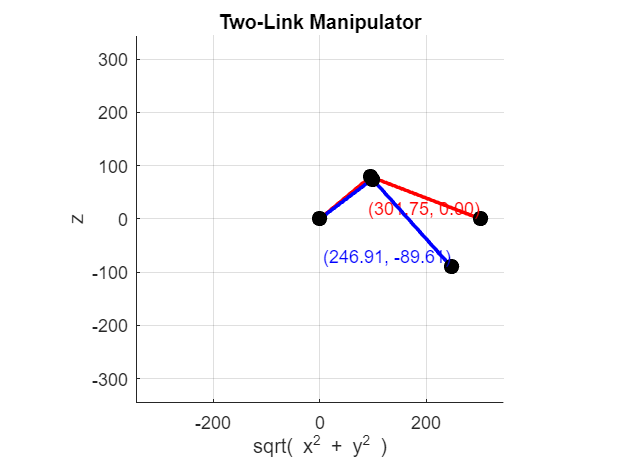

% RED Link plots analytical solution of manipulator
% BLUE Link plots approximate solution of manipulator


% Link lengths
L1 = 124;  % Length of the first link
L2 = 221;  % Length of the second link

% Joint angles (in radians)
theta1 = gamma;  % Angle of the first link with respect to the horizontal
theta2 = phi;  % Angle of the second link with respect to the first link

% Calculate the position of the first joint (base)
x0 = 0;
y0 = 0;

% Calculate the position of the second joint (end of the first link)
x1 = L1 * cos(theta1);
y1 = L1 * sin(theta1);

% Calculate the position of the end of the second link
x2 = x1 + L2 * cos(theta1 + theta2);
y2 = y1 + L2 * sin(theta1 + theta2);

% Plot the links
figure;

hold on;
plot([x0 x1], [y0 y1], 'r-', 'LineWidth', 2);  % First link in red
plot([x1 x2], [y1 y2], 'r-', 'LineWidth', 2);  % Second link in blue

% Plot joints
plot(x0, y0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');  % Base joint
plot(x1, y1, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');  % Second joint
plot(x2, y2, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');  % End effector


coord_text = ['(', num2str(double(x2), '%.2f'), ', ', num2str(double(y2), '%.2f'), ')'];
text(x2, y2, coord_text, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'Color', 'red');

% Joint angles (in radians)
theta1 = gamma_angle;  % Angle of the first link with respect to the horizontal
theta2 = phi_angle;  % Angle of the second link with respect to the first link

% Calculate the position of the first joint (base)
x0 = 0;
y0 = 0;

% Calculate the position of the second joint (end of the first link)
x1 = L1 * cos(theta1);
y1 = L1 * sin(theta1);

% Calculate the position of the end of the second link
x2 = x1 + L2 * cos(theta1 + theta2);
y2 = y1 + L2 * sin(theta1 + theta2);

% Plot the links
hold on;
plot([x0 x1], [y0 y1], 'b-', 'LineWidth', 2);  % First link in red
plot([x1 x2], [y1 y2], 'b-', 'LineWidth', 2);  % Second link in blue


% Plot joints
plot(x0, y0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');  % Base joint
plot(x1, y1, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');  % Second joint
plot(x2, y2, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');  % End effector


coord_text = ['(', num2str(double(x2), '%.2f'), ', ', num2str(double(y2), '%.2f'), ')'];
text(x2, y2, coord_text, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'Color', 'blue');

% Axis settings
axis equal;
xlim([-L1-L2, L1+L2]);
ylim([-L1-L2, L1+L2]);
xlabel('sqrt( x^2 + y^2 )') 
ylabel('z') 
title('Two-Link Manipulator');
grid on;
hold off;



rad2deg(gamma_angle);
rad2deg(phi_angle);

Junk stuff ( to be deleted)

___________________________________________________________________________________________________

jacobian

syms x_1 x_2 x_3

% matrix representing arm-joint angles
f = [   l0*(cos(x_2)*cos(x_1)*cos(x_3)-sin(x_2)*cos(x_1)*sin(x_3))+l1*cos(x_2)*cos(x_1)+l2*cos(x_1) ;

        -(l0*(sin(x_2)*sin(x_1)*sin(x_3)-cos(x_2)*sin(x_1)*cos(x_3))-l1*cos(x_2)*sin(x_1) - l2*sin(x_1)) ;

        l0*(cos(x_2)*sin(x_3)+sin(x_2)*cos(x_3))+l1*sin(x_2) ;

        ];

(jacobian(f, [x_1 ;x_2; x_3]))

$$ans = \begin{array}{l} \left(\begin{array}{ccc} -l_{0}\,\left(\cos\left(x_{2}\right)\,\cos\left(x_{3}\right)\,\sin\left(x_{1}\right)-\sin\left(x_{1}\right)\,\sin\left(x_{2}\right)\,\sin\left(x_{3}\right)\right)-l_{2}\,\sin\left(x_{1}\right)-l_{1}\,\cos\left(x_{2}\right)\,\sin\left(x_{1}\right) & -\sigma_{2}-l_{1}\,\cos\left(x_{1}\right)\,\sin\left(x_{2}\right) & -\sigma_{2}\\ l_{2}\,\cos\left(x_{1}\right)-l_{0}\,\left(\cos\left(x_{1}\right)\,\sin\left(x_{2}\right)\,\sin\left(x_{3}\right)-\cos\left(x_{1}\right)\,\cos\left(x_{2}\right)\,\cos\left(x_{3}\right)\right)+l_{1}\,\cos\left(x_{1}\right)\,\cos\left(x_{2}\right) & -\sigma_{1}-l_{1}\,\sin\left(x_{1}\right)\,\sin\left(x_{2}\right) & -\sigma_{1}\\ 0 & \sigma_{3}+l_{1}\,\cos\left(x_{2}\right) & \sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{0}\,\left(\cos\left(x_{2}\right)\,\sin\left(x_{1}\right)\,\sin\left(x_{3}\right)+\cos\left(x_{3}\right)\,\sin\left(x_{1}\right)\,\sin\left(x_{2}\right)\right)\\ \sigma_{2}=l_{0}\,\left(\cos\left(x_{1}\right)\,\cos\left(x_{2}\right)\,\sin\left(x_{3}\right)+\cos\left(x_{1}\right)\,\cos\left(x_{3}\right)\,\sin\left(x_{2}\right)\right)\\ \sigma_{3}=l_{0}\,\left(\cos\left(x_{2}\right)\,\cos\left(x_{3}\right)-\sin\left(x_{2}\right)\,\sin\left(x_{3}\right)\right) \end{array}$$

var = subs(ans,[x_1,x_2,x_3],[0,0,0])

$$var = \left(\begin{array}{ccc} 0 & 0 & 0\\ l_{0}+l_{1}+l_{2} & 0 & 0\\ 0 & l_{0}+l_{1} & l_{0} \end{array}\right)$$